clear all; close all; clc

dbstop if error

%Choose object detection probability
P_D = 0.98;
%Choose clutter rate
lambda_c = 10;
%Choose object survival probability
P_S = 0.99;

%Choose linear or nonlinear scenario
scenario_type = 'linear';

## Create tracking scenario

switch(scenario_type)
    case 'linear'
        %Create sensor model
        range_c = [-1000 1000;-1000 1000];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Create linear motion model
        T = 1;
        sigma_q = 5;
        motion_model = motionmodel.cvmodel(T,sigma_q);
        
        %Create linear measurement model
        sigma_r = 10;
        meas_model = measmodel.cvmeasmodel(sigma_r);
        
        %Create ground truth model
        nbirths = 12;
        K = 100;
        tbirth = zeros(nbirths,1);
        tdeath = zeros(nbirths,1);
        
        initial_state(1).x  = [ 0; 0; 0; -10 ];            tbirth(1)  = 1;     tdeath(1)  = 70;
        initial_state(2).x  = [ 400; -600; -10; 5 ];       tbirth(2)  = 1;     tdeath(2)  = K+1;
        initial_state(3).x  = [ -800; -200; 20; -5 ];      tbirth(3)  = 1;     tdeath(3)  = 70;
        initial_state(4).x  = [ 400; -600; -7; -4 ];       tbirth(4)  = 20;    tdeath(4)  = K+1;
        initial_state(5).x  = [ 400; -600; -2.5; 10 ];     tbirth(5)  = 20;    tdeath(5)  = K+1;
        initial_state(6).x  = [ 0; 0; 7.5; -5 ];           tbirth(6)  = 20;    tdeath(6)  = K+1;
        initial_state(7).x  = [ -800; -200; 12; 7 ];       tbirth(7)  = 40;    tdeath(7)  = K+1;
        initial_state(8).x  = [ -200; 800; 15; -10 ];      tbirth(8)  = 40;    tdeath(8)  = K+1;
        initial_state(9).x  = [ -800; -200; 3; 15 ];       tbirth(9)   = 60;   tdeath(9)  = K+1;
        initial_state(10).x  = [ -200; 800; -3; -15 ];     tbirth(10)  = 60;   tdeath(10) = K+1;
        initial_state(11).x  = [ 0; 0; -20; -15 ];         tbirth(11)  = 80;   tdeath(11) = K+1;
        initial_state(12).x  = [ -200; 800; 15; -5 ];      tbirth(12)  = 80;   tdeath(12) = K+1;
        
        birth_model = repmat(struct('w',0.03,'x',[],'P',400*eye(motion_model.d)),[1,4]);
        birth_model(1).x = [ 0; 0; 0; 0];
        birth_model(2).x = [ 400; -600; 0; 0];
        birth_model(3).x = [ -800; -200; 0; 0 ];
        birth_model(4).x = [ -200; 800; 0; 0 ];
        
    case 'nonlinear'
        %Create sensor model
        %Range/bearing measurement range
        range_c = [-1000 1000;-pi pi];
        sensor_model = modelgen.sensormodel(P_D,lambda_c,range_c);
        
        %Create nonlinear motion model (coordinate turn)
        T = 1;
        sigmaV = 1;
        sigmaOmega = pi/180;
        motion_model = motionmodel.ctmodel(T,sigmaV,sigmaOmega);
        
        %Create nonlinear measurement model (range/bearing)
        sigma_r = 5;
        sigma_b = pi/180;
        s = [300;400];
        meas_model = measmodel.rangebearingmeasmodel(sigma_r, sigma_b, s);
        
        %Creat ground truth model
        nbirths = 4;
        K = 100;
        tbirth = zeros(nbirths,1);
        tdeath = zeros(nbirths,1);
        
        initial_state(1).x = [0; 0; 5; 0; pi/180];       tbirth(1) = 1;   tdeath(1) = 50;
        initial_state(2).x = [20; 20; -20; 0; pi/90];    tbirth(2) = 20;  tdeath(2) = 70;
        initial_state(3).x = [-20; 10; -10; 0; pi/360];  tbirth(3) = 40;  tdeath(3) = 90;
        initial_state(4).x = [-10; -10; 8; 0; pi/270];   tbirth(4) = 60;  tdeath(4) = K;

        birth_model = repmat(struct('w',0.03,'x',[],'P',diag([1 1 1 1*pi/90 1*pi/90].^2)),[1,4]);
        birth_model(1).x = [0; 0; 5; 0; pi/180];
        birth_model(2).x = [20; 20; -20; 0; pi/90];
        birth_model(3).x = [-20; 10; -10; 0; pi/360];
        birth_model(4).x = [-10; -10; 8; 0; pi/270];
end

## Generate true object data (noisy or noiseless) and measurement data

ground_truth = modelgen.groundtruth(nbirths,[initial_state.x],tbirth,tdeath,K);
ifnoisy = 0;
objectdata = objectdatagen(ground_truth,motion_model,ifnoisy);
measdata = measdatagen(objectdata,sensor_model,meas_model);

## Object tracker parameter setting

P_G = 0.999;            %gating size in percentage
w_min = 1e-4;           %hypothesis pruning threshold
M = 100;                %maximum number of hypotheses kept
r_min = 1e-4;           %Bernoulli component pruning threshold
r_estimate = 0.5;       %Threshold used to extract estimates from Bernoullis
% density_class_handle = feval(@trajectoryGaussianFilteringForm);    %filtering
density_class_handle = feval(@trajectoryAccumulatedStateDensity);    %smoothing-while-filtering
tracker = multiobjectracker();
tracker = tracker.initialize(density_class_handle,P_S,P_G,meas_model.d,w_min,M,r_min,r_estimate);

## Trajectory PMBM filter

PMBMestimates = PMBMtracker(tracker, birth_model, measdata, sensor_model, motion_model, meas_model);

## Ploting

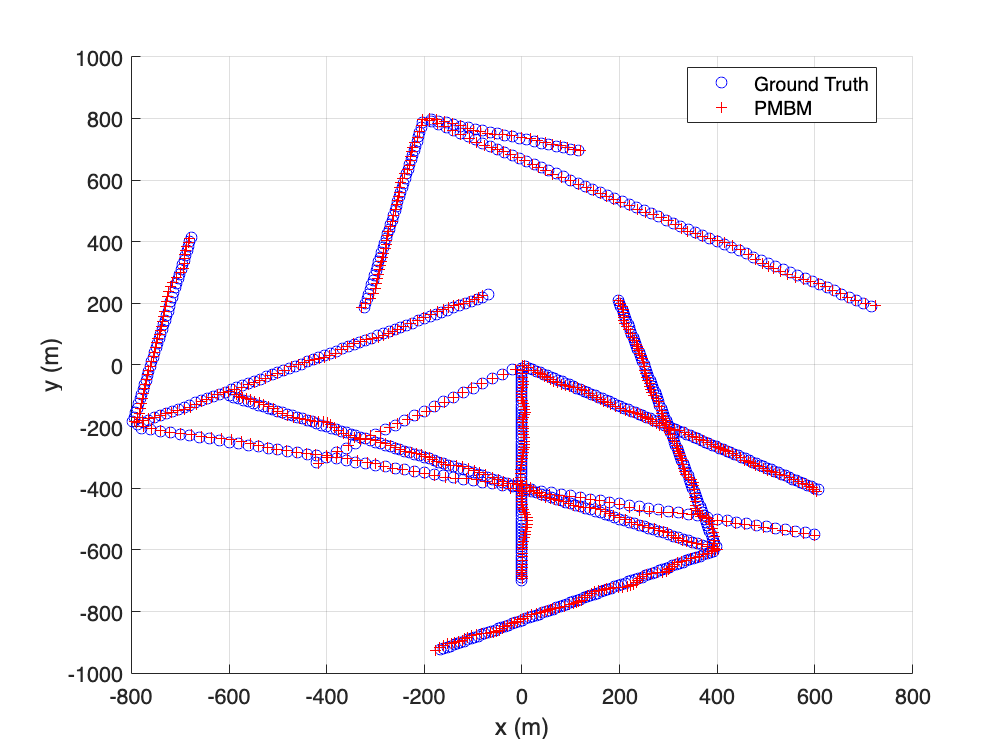

true_state = cell2mat(objectdata.X');
%Extract the set of all trajectories estimates from the last time step
PMBM_estimated_state = cell2mat(PMBMestimates{end}');

%Trajectory plot
figure
hold on
grid on

h1 = plot(true_state(1,:), true_state(2,:), 'bo');
h2 = plot(PMBM_estimated_state(1,:), PMBM_estimated_state(2,:),'r+');

xlabel('x (m)'); ylabel('y (m)')
legend([h1 h2],'Ground Truth','PMBM', 'Location', 'best')
set(gca,'FontSize',12)